# Lab 7 SNS

## Syed Muhammad Asad Ali

### sa09475

#### Task 1

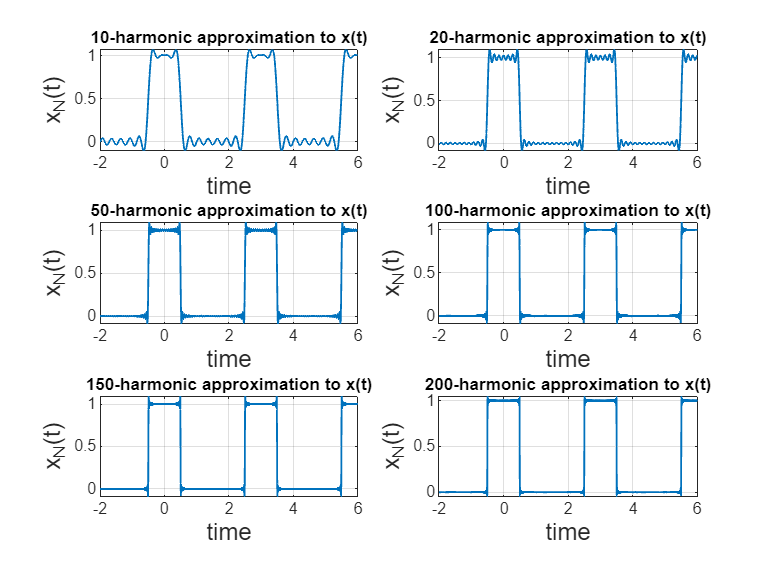

clc; clear; close all
% Set the dc term "a0".
a0 = 1/3;
% Define number of terms
N_values = [10, 20, 50, 100, 150, 200];
% Create a vector of time instants.
t = -2:1/200:6;
% Set the fundamental frequency.
T0 = 3;
omg0 = 2*pi/T0;
figure; 
for i=1: length(N_values)
    N = N_values(i);
    k = 1:N;
    ak = 2*sin(pi*k/3)./(pi*k);
    
    % Compute approximation to signal using N-th harmonic
    xtN = a0;
    for kk = 1:N
        xtN = xtN + ak(kk) * cos(kk * omg0 * t);
    end
 % Plot Nth-harmonic approximation.
 subplot(3, 2, i)
 plot(t, xtN, 'linewidth',1);
 grid on; xlabel('time','Fontsize',13);
 ylabel('x_N(t)','Fontsize',13)
 title([num2str(N) ...
 '-harmonic approximation to x(t)']);
 end

#### Task 2

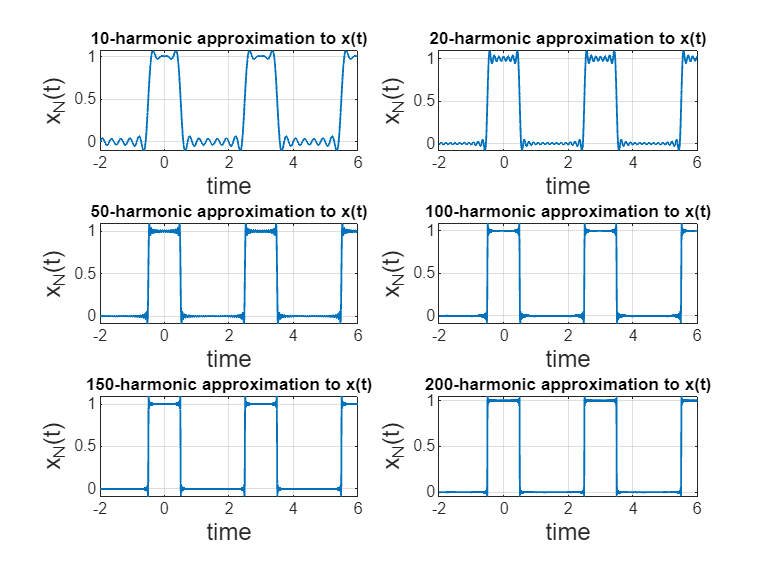

% Set the dc term "a0".
a0 = 1/3;
% Define number of terms
N_values = [10, 20, 50, 100, 150, 200];
% Create a vector of time instants.
t = -2:1/200:6;
% Set the fundamental frequency.
T0 = 3;
omg0 = 2*pi/T0;
figure; 
for i=1: length(N_values)
    N = N_values(i);
    k = 1:N;
    ak = 2*sin(pi*k/3)./(pi*k);
    dk = abs(ak);
    thetak = zeros(size(ak));  
    thetak(ak < 0) = pi;
    % Compute approximation to signal using N-th harmonic
    xtN = a0;
    for kk = 1:N
        xtN = xtN + dk(kk) * cos(kk * omg0 * t - thetak(kk));
    end
% Plot Nth-harmonic approximation.
subplot(3, 2, i)
plot(t, xtN, 'linewidth',1);
grid on; xlabel('time','Fontsize',13);
ylabel('x_N(t)','Fontsize',13)
title([num2str(N) '-harmonic approximation to x(t)'])
end

**Observation**:  In this code we are using a shorter or also called a truncated fourier series model to get close to a periodic signal x(t). We first describe the dc term and then go through the values array and define a number of other terms. By finding the fourier coefficients we are actually finding how much cosine terms adds to the expansion of the fourier series.we also are showing that how the approximation gets more accurate as more terms keep being added.

#### Task 3

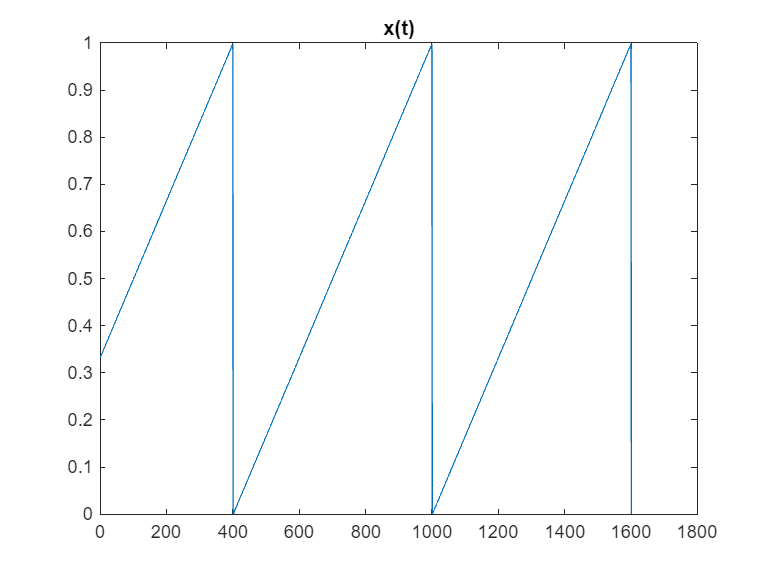

% task 3
a = 1;
T0 = 3;
N = 20;
t = -2:1/N/10:6;
xt = mod((a*t)/T0, a);
figure; plot(xt)
title ("x(t)")

a0 = 1/2;
Narr = [5 10 20 30 40 50];
for i = 1:6
    N = Narr(i);
    k = 1:N;
    ak = 2*a*((sin(2*pi*k)./(2*pi*k)) + ((cos(2*pi*k)-1)./(4*(pi.^2)*(k.^2))));
    bk = 2*a*((sin(2*pi*k)./(4*(pi.^2)*(k.^2))) + (cos(2*pi*k)./(2*pi*k)));
    t=-2:1/N/10:6;
    T0 = 3;
    omg0 = 2*pi/T0;
    xtN = a0;
    for kk=1:N
        xtN = xtN + ak(kk)*cos(kk*omg0*t) + bk(kk)*sin(kk*omg0*t);
    end
subplot (3,2,i); plot(t, xtN, 'linewidth',1);
grid on; xlabel('time','Fontsize',13);
ylabel('x_N(t)','Fontsize',13)
title([num2str(N) '-harmonic approximation to x(t)']);
end

**Observation**:  In this code we define a periodic signal x(t) like a sawtooth waveform. Then this sawtooth waveform is approximated using fourier series with different numbers of harmonics. First we plot the original signal x(t) then for each value of N (which is number of harmonics ) in the array Narr, then we calculate coefficeitns ak and bk. Then by iteration we find the Fourier series approximation xtN using the earlier calculated coefficients and plot it against time. This process is repeated for each value of N in Narr. the more terms we add the more resemblance we get with the original signal.

#### Task 4

a0 = 1/pi;
Narr = [5 10 15 20 25 50];
for i = 1:6
N = Narr(i);
k = 1:N;
t=-2:1/N/10:6;
T0 = 3;
omg0 = 2*pi/T0;
xtN = a0;
for kk=1:N
if mod(kk, 2) == 0
ak =-2./(pi*((kk.^2)-1));
else
ak = 0;
end
if kk == 1
bk = 1/2;
else
bk = 0;
end
xtN = xtN + ak*cos(kk*omg0*t) + bk*sin(kk*omg0*t);
end
subplot (3,2,i); plot(t, xtN, 'linewidth',1);
grid on; xlabel('time','Fontsize',13);
ylabel('x_N(t)','Fontsize',13)
title([num2str(N) '-harmonic approximation to x(t)']);
end

**Observation**:  Firstly we define fundamental frequency of signal which is ⅓ and set dc term a0 to 1/pi.By the iterations for different numbers of harmonics(N),we calculate Fourier coefficients ak and bk based on conditions for even and odd harmonics. for even harmonics ak is found as-2/(pi*((kk.^2)-1)), for odd harmonics, it is set to zero.The DC term (k=1) is treated separately, with bk set to 1/2 and all other bk terms set to zero.Then we plot resulting Fourier series approximation xtN against time for each N, which actually tells us how the addition of more harmonics effects the accuracy of the approximation. 

#### Task 5

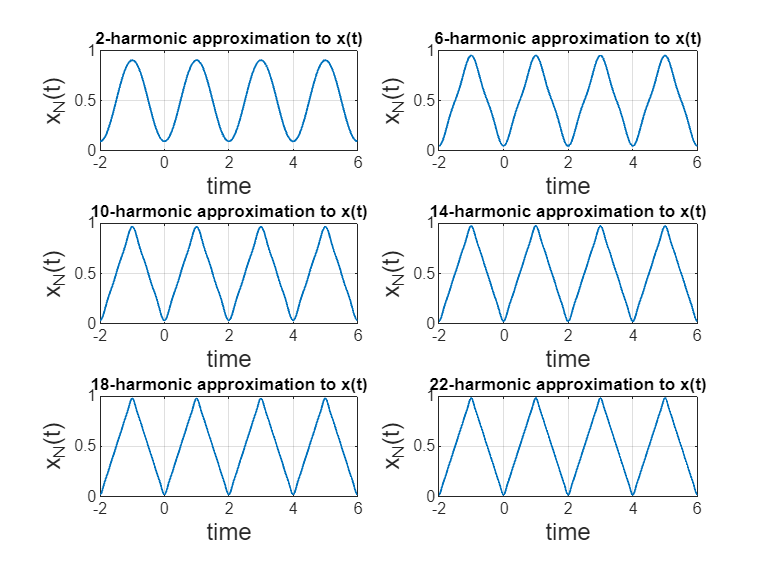

m = 1;
a0 = m/2;
Narr = [2 6 10 14 18 22];
for i = 1:6
N = Narr(i);
k = 1:N;
ak = (4*m./((k.^2)*(pi^2))).*(2*cos((k*pi)./2) - cos(k*pi) - 1);
bk = 0;
t=-2:1/N/10:6;
T0 = 4;
omg0 = 2*pi/T0;
xtN = a0;
for kk=1:N
xtN = xtN + ak(kk)*cos(kk*omg0*t) + bk*sin(kk*omg0*t);
end
subplot (3,2,i); plot(t, xtN, 'linewidth',1);
grid on; xlabel('time','Fontsize',13);
ylabel('x_N(t)','Fontsize',13)
title([num2str(N) '-harmonic approximation to x(t)']);
end

**Observation**:  In this code we calculator and plot the N-th harmonic approximation of a periodic signal. We then iterate over six different values of N specified in the array Narr which is from 2 to 22. in each iteration fourier coefficients ak is calculated based on the formula. We set bk coefficients to zero. Then we reconstruct signal and plot against time. Each plot shows us a different number of harmonics, showing how the approximation improves as more terms are included.

### Post Lab

#### Task 6 (i)

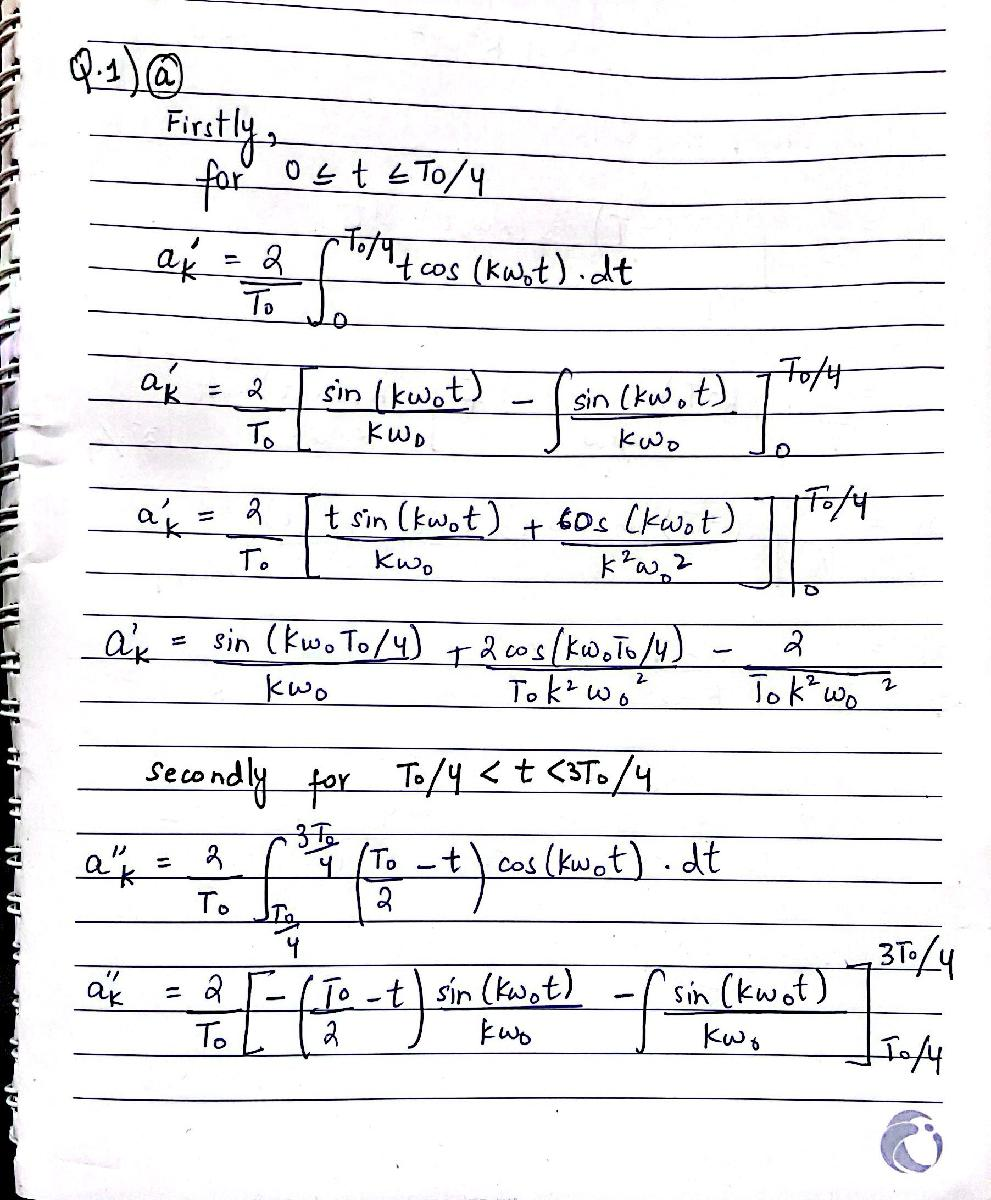

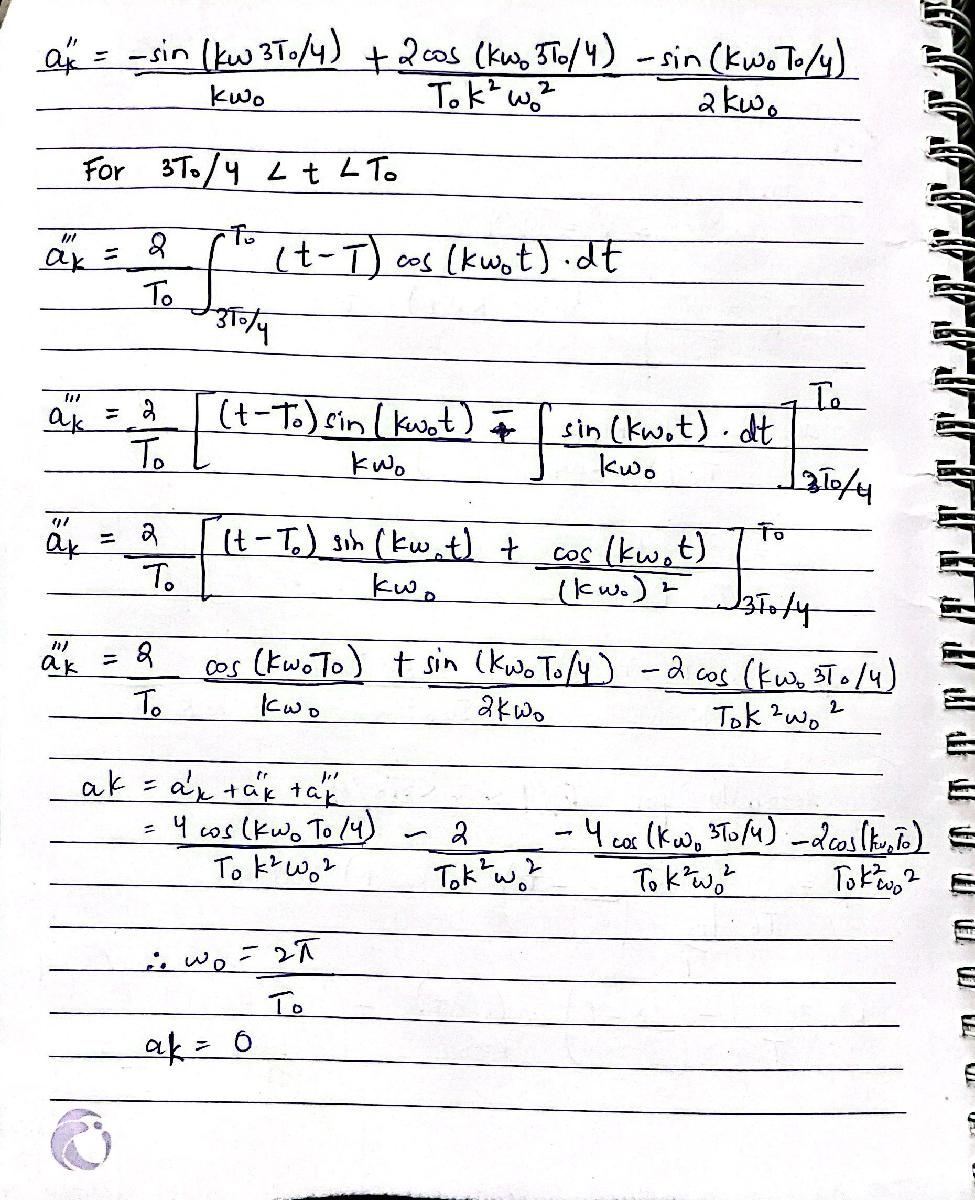

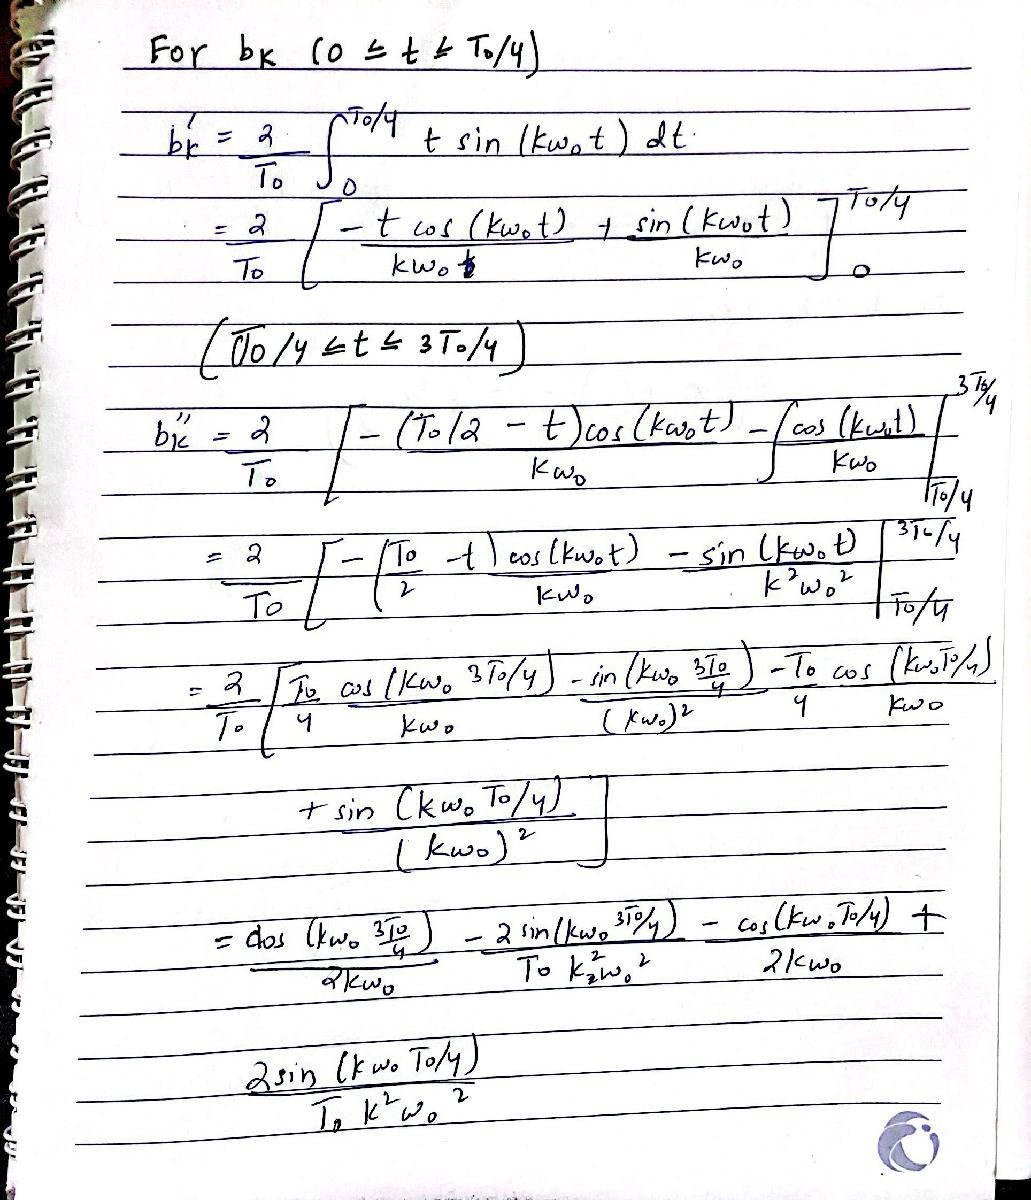

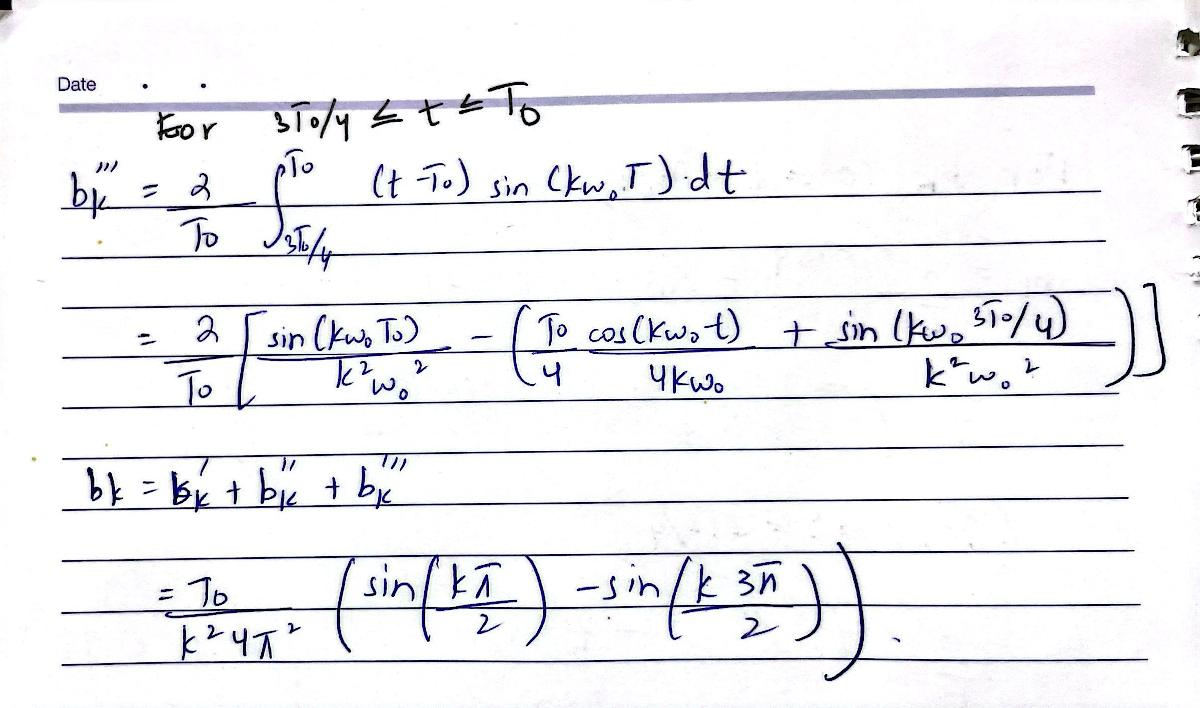

#### Task 6 (ii)

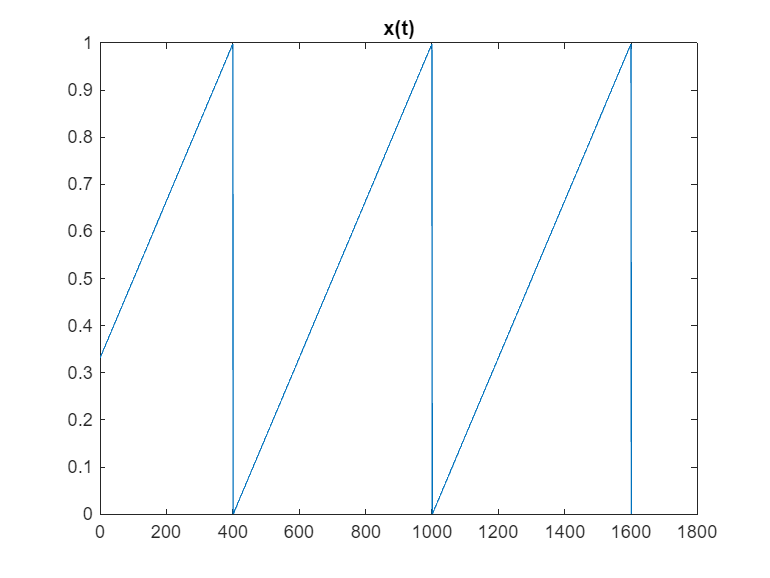

a = 1;
T0 = 3;
N = 20;
t = -2:1/N/10:6;
xt = mod((a*t)/T0, a);
figure; plot(xt)
title ("x(t)")

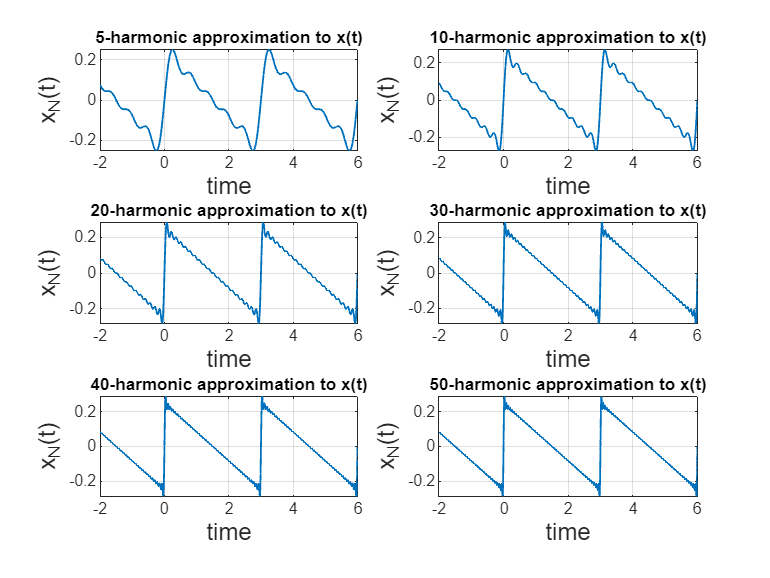

a0 = 1/2;
Narr = [5 10 20 30 40 50];
for i = 1:6
N = Narr(i);
k = 1:N;
ak = 2*a*((sin(2*pi*k)./(2*pi*k)) + ((cos(2*pi*k)-1)./(4*(pi.^2)*(k.^2))));
bk = 2*a*((sin(2*pi*k)./(4*(pi.^2)*(k.^2))) + (cos(2*pi*k)./(2*pi*k)));
t=-2:1/N/10:6;
T0 = 3;
omg0 = 2*pi/T0;
xtN = 0;
for kk=1:N
ck = 0.5*(ak(kk) - (bk(kk)*j));
xtN = xtN + ck*exp(kk*omg0*t*j);
end
% Plot Nth-harmonic approximation.
subplot (3,2,i); plot(t, real(xtN), 'linewidth',1);
grid on; xlabel('time','Fontsize',13);
ylabel('x_N(t)','Fontsize',13)
title([num2str(N) '-harmonic approximation to x(t)']);
end